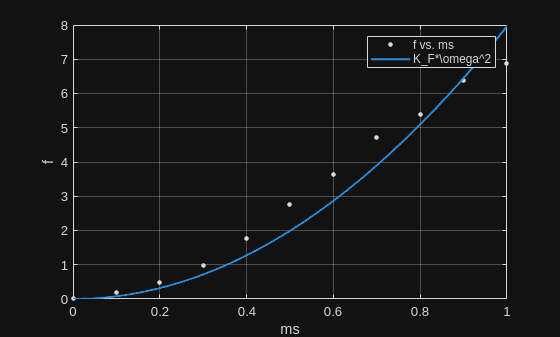

%% Estimar K_F
clear,clc

ms = 0:0.1:1;
f = [120 140 170 220 300 400 490 600 670 770 820];
f = f - 120;
f = 9.81*f/1000;
%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( ms, f );

% Set up fittype and options.
ft = fittype( 'a*power(x,2)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.469390641058206;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'f vs. ms', 'K_F*\omega^2', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'ms', 'Interpreter', 'none' );
ylabel( 'f', 'Interpreter', 'none' );
grid on

disp(fitresult)

     General model:
     fitresult(x) = a*power(x,2)
     Coefficients (with 95% confidence bounds):
       a =       7.965  (7.142, 8.788)
